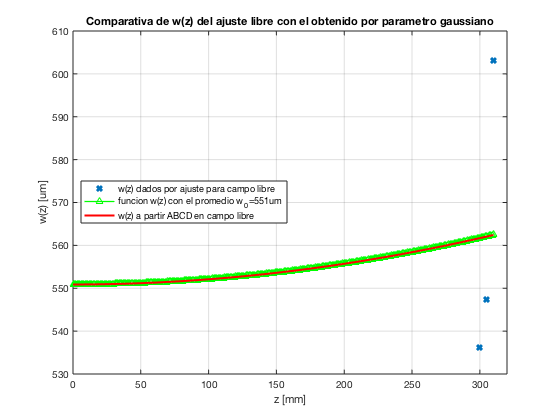

close all;
clear all;

%es para el nombre al exportar y titulos
titulo_img_fig_libre = 'libre';
titulo_img_fig_ancho = 'ancho';
titulo_img_fig_angosto = 'angosto';

%Obtencion de w0 a partir de los w_prom a cada distancia 
lambda0 = 632.8E-9; 
pixel = 25E-6; %tamano de cada pixel

% nomenclatura: w_prom_z = [w_prom_300 w_prom_305 w_prom_310]
%libre
w_prom_z_libre = [21.449 21.893 24.123]; %estos son pixeles
w_prom_z_libre = w_prom_z_libre * pixel;
%ancho
w_prom_z_ancho = [31.259 30.032 30.304];
w_prom_z_ancho = w_prom_z_ancho * pixel;
%angosto
w_prom_z_angosto = [22.006 22.607 22.955];
w_prom_z_angosto = w_prom_z_angosto * pixel;

z_a = [300E-3 305E-3 310E-3]; %posiciones de captura de imagen

%Parametros A y C del sistema de lentes para haz colimado 
% f1 + f2 = d
% A = ys/ye = -f2/f1

%Amplif = ancho => f1<0 y f2>0
%Enfoque = angosto => f1>0 y f2<0
%+200, +100, +60, +50 y +30 (plano convexas) 
%-100, −50, −40 y −30 (plano concavas) 
f_concava = [-100 -50 -40 -30]; %en mm
f_convexa = [200 100 60 50 30];
f_concava = f_concava.*1E-3; %en metros
f_convexa = f_convexa.*1E-3; 

w0_prom = 5.5088e-04; %obtenido del camino libre
%A_sistema = mean(w_prom_z) / w0_prom;

%veo que amplificaciones puedo obtener
%for l=1:5
%    for m=1:4
%        A_propuesta = -f2(l)/f1(m);
%        fprintf('f2(%d)=%d,f1(%d)=%d,A=%.4f\n',l,f2(l),m,f1(m),A_propuesta);
%    end
%end

%voy a cargar dos posibles configuraciones y compararlas
% sist_ancho es una matriz con las filas como el sist y columnas como
% distancias focales
sist_ancho = [f_concava(3) f_convexa(3) ; f_concava(3) f_convexa(4)];

z= 0:0.001:0.310; %son 0 a 300mm (esta en metros)

%Parametro gaussiano, ABCD
%decido usar w0 = w0_prom obtenido del camino libre
w0 = w0_prom;
q_e_inv = -j*(lambda0/(pi*w0^2));
q_s_inv_sist_1 = [];
q_s_inv_sist_2 = [];
%Calculo el valor de 1/q_s en cada punto del recorrido
%[A,B,C,D] = arreglo(z,d0,f1,f2)
%d0=0.05m=5cm=50mm
for i=1:length(z)
    [abcd_libre] = ABCD_libre(z(i));
    q_s_inv_libre(i) = (abcd_libre(2,1) + abcd_libre(2,2)*q_e_inv) / (abcd_libre(1,1) + abcd_libre(1,2)*q_e_inv);
    
    [abcd_ancho_1] = arreglo(z(i),0.05,sist_ancho(1,1),sist_ancho(1,2));
    q_s_inv_sist_1(i) = (abcd_ancho_1(2,1) + abcd_ancho_1(2,2)*q_e_inv) / (abcd_ancho_1(1,1) + abcd_ancho_1(1,2)*q_e_inv);
    [abcd_ancho_2] = arreglo(z(i),0.05,sist_ancho(2,1),sist_ancho(2,2));
    q_s_inv_sist_2(i) = (abcd_ancho_2(2,1) + abcd_ancho_2(2,2)*q_e_inv) / (abcd_ancho_2(1,1) + abcd_ancho_2(1,2)*q_e_inv);

end

R_z_inv_libre = real(q_s_inv_libre);
w_z_libre = sqrt( -lambda0 ./ (pi*(imag(q_s_inv_libre))));
R_z_inv_sist_1 = real(q_s_inv_sist_1);
w_z_sist_1 = sqrt( -lambda0 ./ (pi*(imag(q_s_inv_sist_1))) );
R_z_inv_sist_2 = real(q_s_inv_sist_2);
w_z_sist_2 = sqrt( -lambda0 ./ (pi*(imag(q_s_inv_sist_2))) );


%Verificacion en campo libre 
%w0 debe coincidir para ABCD y funcion w(z)
figure()
plot(1E3*z_a,1E6*w_prom_z_libre,'x','LineWidth',3); 
hold on;
plot(1E3*z,1E6*sqrt((w0_prom^2 *( 1+ ( (z*lambda0)/(pi*w0_prom^2) ).^2 ))  ),'-g','marker','^','LineWidth',1.2);%w(z) con el w0 promedio
plot(1E3*z,1E6*w_z_libre,'-r','LineWidth',2); %w dado por param gaussiano
grid on;
title(sprintf('Comparativa de w(z) del ajuste %s con el obtenido por parametro gaussiano',titulo_img_fig_libre));
ylabel('w(z) [um]');
xlabel('z [mm]');
axis([0 320 530 610]);
legend('w(z) dados por ajuste para campo libre',sprintf('funcion w(z) con el promedio w_0=%.fum',w0_prom*1E6),'w(z) a partir ABCD en campo libre','location','west');
%print(sprintf('fig_w(z)_ABCD_%s',titulo_img_fig_libre),'-dpng');

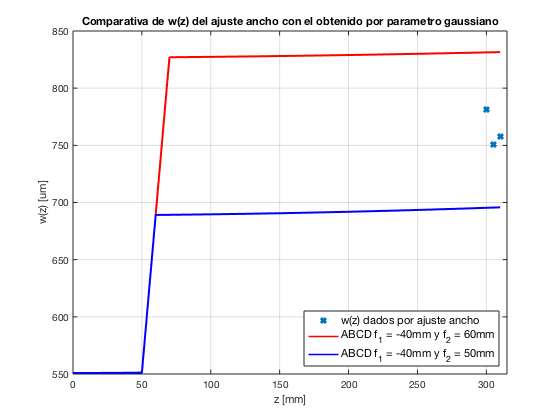


%Ancho
figure()
plot(1E3*z_a,1E6*w_prom_z_ancho,'x','LineWidth',3); 
hold on;
plot(1E3*z,1E6*w_z_sist_1,'-r','LineWidth',1.5); %w dado por param gaussiano
plot(1E3*z,1E6*w_z_sist_2,'-b','LineWidth',1.5);
grid on;
title(sprintf('Comparativa de w(z) del ajuste %s con el obtenido por parametro gaussiano',titulo_img_fig_ancho));
ylabel('w(z) [um]');
xlabel('z [mm]');
axis([0 315 550 850]);
legend(sprintf('w(z) dados por ajuste %s',titulo_img_fig_ancho),sprintf('ABCD f_1 = %dmm y f_2 = %dmm',1E3*sist_ancho(1,1),1E3*sist_ancho(1,2)),sprintf('ABCD f_1 = %dmm y f_2 = %dmm',1E3*sist_ancho(2,1),1E3*sist_ancho(2,2)),'location','southeast','FontSize',11);

%print(sprintf('fig_w(z)_ABCD_%s',titulo_img_fig_ancho),'-dpng');


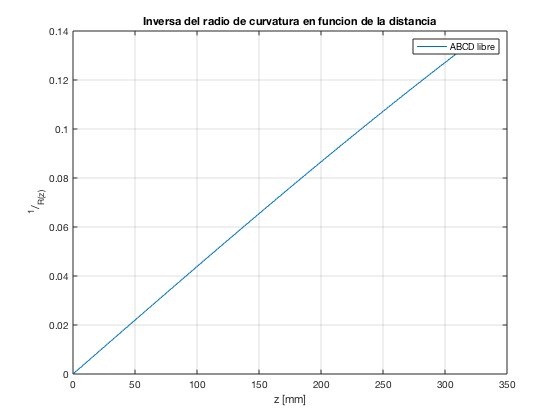

%REVISAR PARA ANCHO

figure()
plot(1E3*z , R_z_inv_libre);
hold on;
%plot(1E3*z , R_z_inv_sist_1,'-r');
%plot(1E3*z , R_z_inv_sist_2,'-b');
grid on;
title('Inversa del radio de curvatura en funcion de la distancia');
ylabel('^{1}/_{R(z)}');
xlabel('z [mm]');
%axis([0 315 0 25]);
legend('ABCD libre',sprintf('ABCD f_1 = %dmm y f_2 = %dmm',1E3*sist_ancho(1,1),1E3*sist_ancho(1,2)),sprintf('ABCD f_1 = %dmm y f_2 = %dmm',1E3*sist_ancho(2,1),1E3*sist_ancho(2,2)));